## Problem 1

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

### Part a) 

rm = 3397; % km
alt_p = 500; % km 
rp = rm + alt_p; % km
vinf = 2.64; % km/s
mu = 42828.314258067;
a = -mu/vinf^2

a = -6.1450e+03

energy = -mu/(2*a)

energy = 3.4848

e = 1 - rp/a

e = 1.6342

h = sqrt(-mu^2/(2*energy)*(1-e^2))

h = 2.0968e+04

p = a*(1-e^2)

p = 1.0265e+04

delta = 2*asin(1/e)

delta = 1.3170

delta_deg = rad2deg(delta)

delta_deg = 75.4585

thinf = delta/2 + pi/2

thinf = 2.2293

thinf_deg = rad2deg(thinf)

thinf_deg = 127.7292

### Part b)

b = abs(a)*sqrt(e^2-1)

b = 7.9423e+03

b2 = sin((pi-delta)/2)*(rp+abs(a))

b2 = 7.9423e+03

thb = -acos(b/(rp+abs(a)))

thb = -0.6585

thb_deg = rad2deg(thb)

thb_deg = -37.7292

rb_mag = p/(1+e*cos(thb))

rb_mag = 4.4778e+03

rb = rb_mag*[cos(thb),sin(thb)]'

rb = 	1.0e+03 *

    3.5416
   -2.7401


vb_mag = sqrt(2*(energy+mu/rb_mag))

vb_mag = 5.1087

thb_dot = h/rb_mag^2

thb_dot = 0.0010

gamma = -acos(rb_mag*thb_dot/vb_mag)

gamma = -0.4113

gamma_deg = rad2deg(gamma)

gamma_deg = -23.5672

vb = vb_mag*[sin(gamma), cos(gamma)]

vb =    -2.0426    4.6826



RCI = [cos(thb) sin(thb); -sin(thb) cos(thb)];
ICR = RCI.';

vb_xy = ICR*vb'

vb_xy =     1.2499
    4.9534


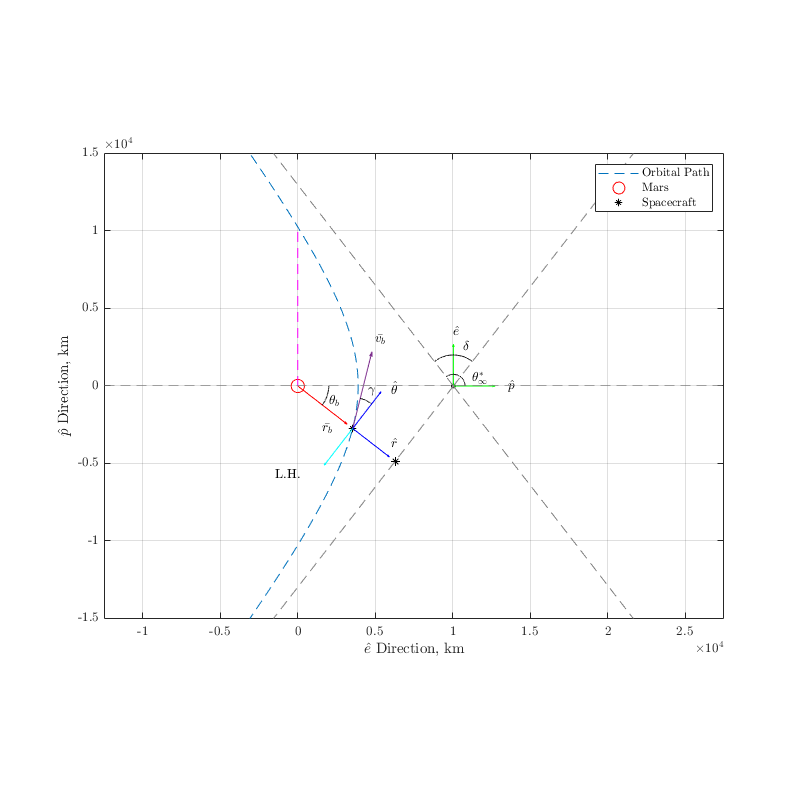


% Plotting
th_plot = linspace(-thinf*.8,thinf*.8,2^10);
r_plot = p./(1+e*cos(th_plot));
r_xy = [r_plot.*cos(th_plot); r_plot.*sin(th_plot)]';
plot(r_xy(:,1),r_xy(:,2),'--','MarkerSize',.1) % plot orbital path % -(rp+abs(a))
hold on

% Plotting Points
plot(0,0,'ro','MarkerSize',10) % Mars
plot(rb(1),rb(2),'k*','markersize',5) % spacecraft
plot(rb(1)*b/rb_mag,rb(2)*b/rb_mag,'k*') % aim point
plot(rp+abs(a),0,'ko','markersize',3) % center

% r and v
quiver(rb(1),rb(2),'r') % rb vector
quiver(rb(1),rb(2),vb_xy(1),vb_xy(2),1e3,'color','#7E2F8E') % vb vector

% Unit Vectors
quiver(rb(1),rb(2),cos(thb),sin(thb),3e3,'b')% r hat 
quiver(rb(1),rb(2),-sin(thb),cos(thb),3e3,'b')% th hat
quiver(rb(1),rb(2),sin(thb),-cos(thb),3e3,'c')% local horizon
quiver(rp+abs(a),0,3e3,0,'g')
quiver(rp+abs(a),0,0,3e3,'g')

% Hyperbolic Constraint Lines
beta = (pi-delta)/2;
plot([rp+abs(a), cos(beta)*1e10],[0 sin(beta)*1e10],'--','color','#828282')
plot([rp+abs(a), cos(beta)*1e10],-[0 sin(beta)*1e10],'--','color','#828282')
plot([rp+abs(a), -cos(beta)*1e10],[0 sin(beta)*1e10],'--','color','#828282')
plot([rp+abs(a), -cos(beta)*1e10],-[0 sin(beta)*1e10],'--','color','#828282')
yline(0,'--','color','#828282')
plot([0,0],[0,p],'--','Color','#FF00FF') % semi-latus rectum
plotcircle(rp+abs(a),0,beta,pi-beta,2e3) % delta
plotcircle(rb(1),rb(2),thb+pi/2,thb+pi/2-gamma,2e3) % gamma
plotcircle(0,0,0,thb,2e3) % thb
plotcircle(rp+abs(a),0,0,thinf,.75e3)

% Labels
text(rp+abs(a),.35e4,'$\hat{e}$') % ehat
text(rp+abs(a)+.35e4,0,'$\hat{p}$') % phat
text(rb(1)+.25e4,rb(2)+.25e4,'$\hat{\theta}$') % thhat
text(rb(1)-.5e4,rb(2)-.3e4,'L.H.') % lh
text(rb(1)+.25e4,rb(2)-.1e4,'$\hat{r}$') % rhat
text(rp+abs(a)+.6e3,.25e4,'$\delta$') % delta
text(rp+abs(a)+1.2e3,.5e3,'$\theta^{*}_{\infty}$') % thinf
text(rb(1)+.1e4,rb(2)+.25e4,'$\gamma$') % gamma
text(.2e4,-1e3,'$\theta_{b}$') % thb
text(rb(1)-2e3,rb(2),'$\bar{r_{b}}$')
text(.5e4,.3e4,'$\bar{v_{b}}$')

% Plot Parameters
grid on
axis equal
xmin = -2e4; xmax = 2e4; ymin = -1.5e4; ymax = 1.5e4;
xlim([xmin xmax]+.75e4); ylim([ymin ymax])
set(gcf,'position',[0,0,800,800])
xlabel('$\hat{e}$ Direction, km')
ylabel('$\hat{p}$ Direction, km')
legend('Orbital Path','Mars','Spacecraft','')

### Part c)

gmatreport = importdata('problem1report_edited.txt');
% gmatreport = importdata('problem1report.txt');
gmatdata = num2cell(gmatreport.data);
gmatheaders = gmatreport.colheaders;
cell2table(gmatdata(17:23,:),'variablenames',gmatheaders)

ans = 7×8 table
      TA       RMAG      VMAG     Energy    VelPeriapsis    SemilatusRectum     FPA      HMAG 
    ______    ______    ______    ______    ____________    _______________    ______    _____

    301.88      5510     4.745    3.4848       5.3804            10266         126.68    20968
    308.64      5081    4.8814    3.4848       5.3804            10266         122.28    20968
     315.8    4727.3    5.0089    3.4848       5.3804            10266         117.68    20968
    323.24    4445.7    5.1222    3.4848       5.3804            10266         112.96    20968
    331.05    4224.7    5.2197    3.4848       5.3804            10266         108.03    20968
    339.75    4052.6    5.3015    3.4848      

### Part d)

vp = sqrt(mu*(2/rp - 1/a))

vp = 5.3805

vcp = sqrt(mu/rp)

vcp = 3.3151

dv = vcp - vp

dv = -2.0654

Function 1: plot circle

function plotcircle(x0,y0,theta0,thetaf,r)
th = linspace(theta0,thetaf,2^10);
x = r*cos(th)+x0;
y = r*sin(th)+y0;
plot(x,y,'k')
end